# Read Barcode Image in 4 Lines of Code

In this exercise, we will read and decode a barcode in an image using a built-in MATLAB functions.

## Load and Display Image

Read an image containing a barcode into the workspace using [`imread`](https://www.mathworks.com/help/matlab/ref/imread.html). Then display the image with [`imshow`](https://www.mathworks.com/help/matlab/ref/imshow.html).

Example code:

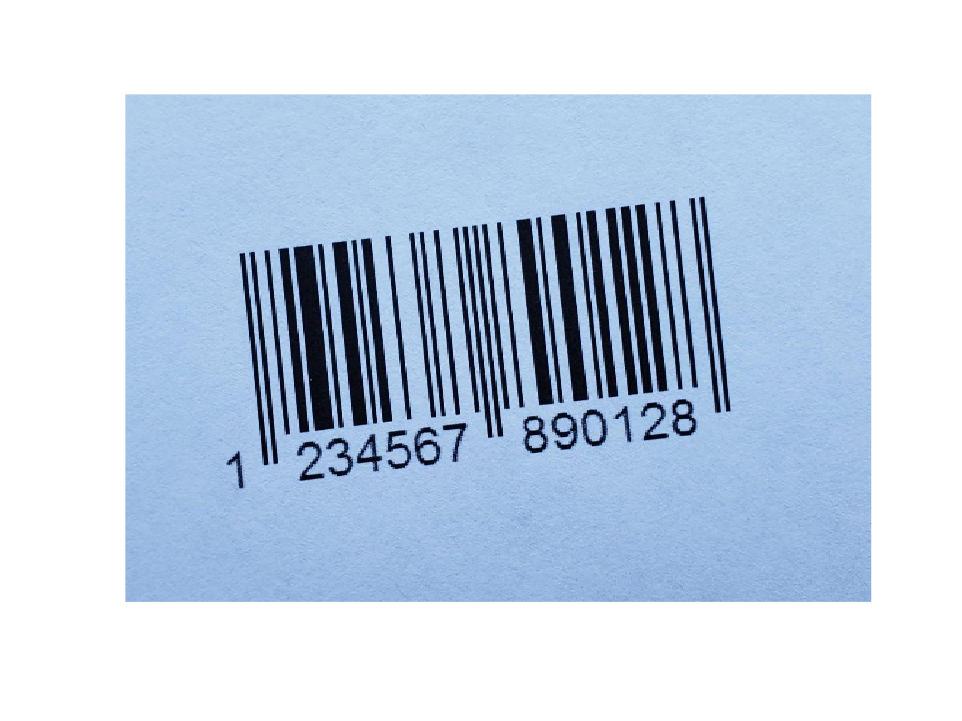

I = imread("barcode1D.jpg");
imshow(I)

## Detect and Decode Barcode Message

Detect the barcode and decode its message using [`readBarcode`](https://www.mathworks.com/help/vision/ref/readbarcode.html).

Example Code:

msg = readBarcode(I);
disp("Decoded barcode message: " + msg)

Decoded barcode message: 1234567890128


## Bonus: Annotate Original Image with Barcode Location and Message Text

Calling `readBarcode` with more explicit input and output arguments allows for us to grab the associated meta data, including the location of the barcode finder patterns in the image.

[msg,detectedFormat,loc] = readBarcode(I,'1D')

msg = "1234567890128"

detectedFormat = "EAN-13"

loc =    211   401
   932   401


### Insert our image annotations.

Annotate a line that marks the finder pattern locations on the image.Then, annotate the barcode message text onto the image.

I_line = insertShape(I,"line",loc,LineWidth=5);
I_text = insertText(I_line,loc(1,:),msg,"FontSize",30);

View our annotated image result.

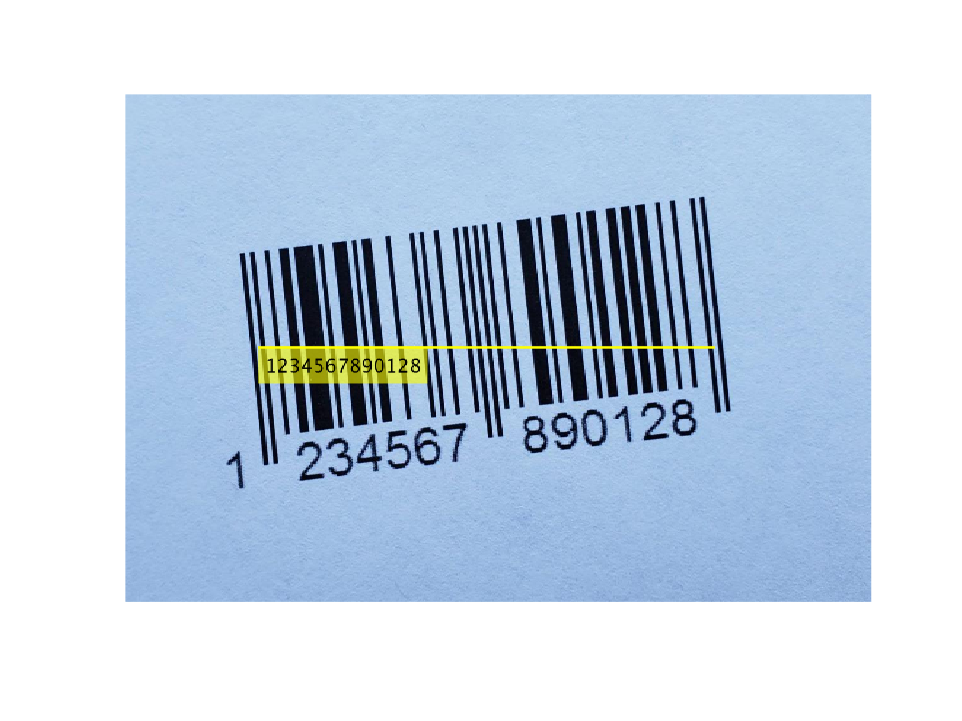

imshow(I_text)

*Copyright 2025, The MathWorks, Inc.*